# Probelm Statement

For the plant** G(s) = 1/s(s+6)** design a **phase-lead** controller for damping ratio **ζ = 0.4 **and natural frequency **15 rad/sec**.

What is the phase margin and gain margin of the compensated system?

# Solution

### Clearing Workspace

close all;
clear;
clc;

### System without a controller

s=tf('s');
G=1/(s*(s+6));

Gcl = Closedloop Transfer Function

Gcl = G/(1+G); % system without controller

Alternatively

%Gcl = feedback(G, 1, -1);

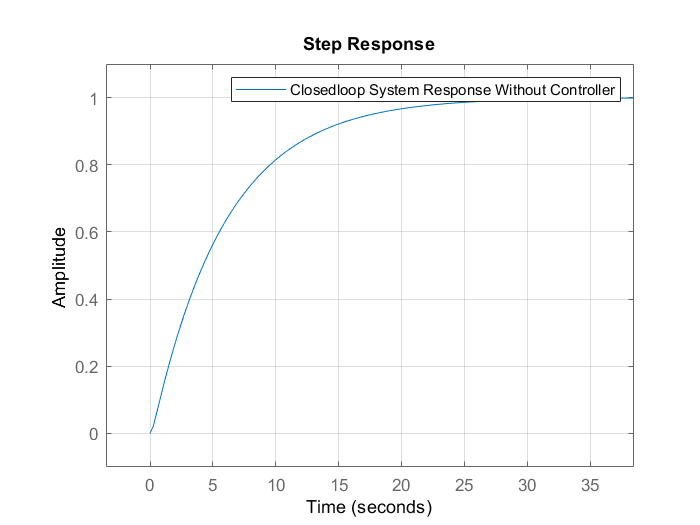

step(Gcl); % plotting step response
grid on;
setAxisLimits(axis);
legend('Closedloop System Response Without Controller');

Poles fo the system without controller

disp(pole(Gcl));

         0
   -6.0000
   -5.8284
   -0.1716



One of the pole is on the imaginary axis, and therefore, the system without controller is marginally stable.

Time domain parameters of system

stepinfo(Gcl)

ans = struct with fields:
        RiseTime: 12.8096
    SettlingTime: 22.9766
     SettlingMin: 0.9016
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 42.6770


# Designing a Phase Lead Controller

**ζ = 0.4**

**ωn = 15**

zita = 0.4;
wn = 15;
desiredPoles = roots([1 2*zita*wn wn^2]);

Root Locus must pass throught desired poles.

disp(desiredPoles);

  -6.0000 +13.7477i
  -6.0000 -13.7477i



Root Locus of a system with a simple proportional controller

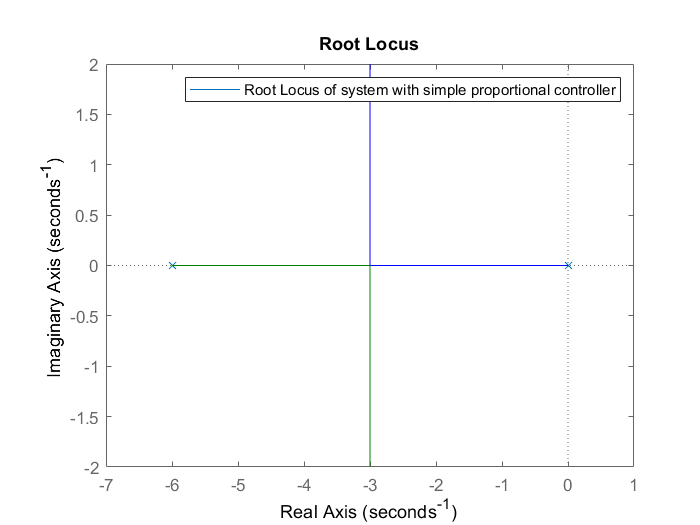

figure;
rlocus(G);
legend('Root Locus of system with simple proportional controller');

We can see that no matter what, the root locus doesn't pass through **desired poles.**

syms s1
G1=1/(s1*(s1+6));
phi=double(angle(subs(G1,s1,-6+13.74i)))*180/pi;
sphi=180-phi;

The zero of the controller is usually taken just below the desired poles, but as in this system, a pole already exists at S = -6.

∴ We take the zero of the controller slightly towards left of -6. i.e S = -7 or **Z = 7**.

z=-7;
p=z-13.7477/tand(90-sphi);
disp(p);

  -13.0034



And thus we the pole of the controller as **-13 **or **P = 13**.

Then we find out **k **using magnitude criteria.


Ds=(s1-z)/(s1-p);
k=1/(double(abs(subs(Ds*G1,-6+13.7477i))))

k = 230.8210

Thus at k = 230.5863, the RL passes through the desired pole location.

## Verification of design

Ds = Controller Transfer Function

Ls = Closedloop Transfer Function with Controller

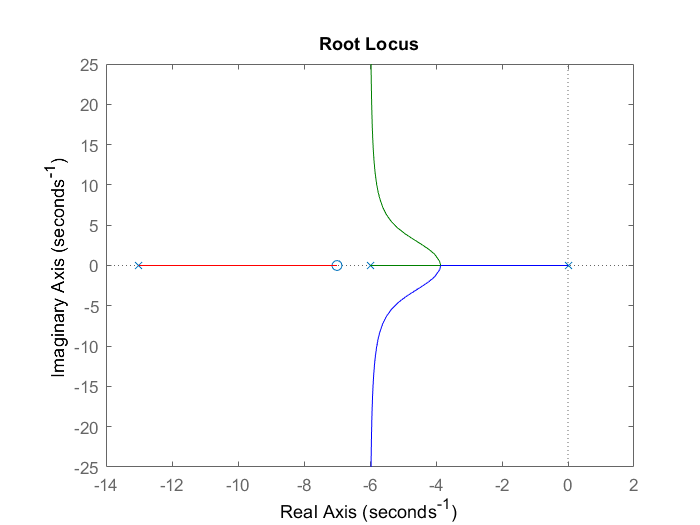

Ds = (s-z)/(s-p);
Ls = k*Ds*G/(1+k*Ds*G);
%Ls = feedback(k*Ds*G, 1, -1);
figure;
rlocus(Ds*G);

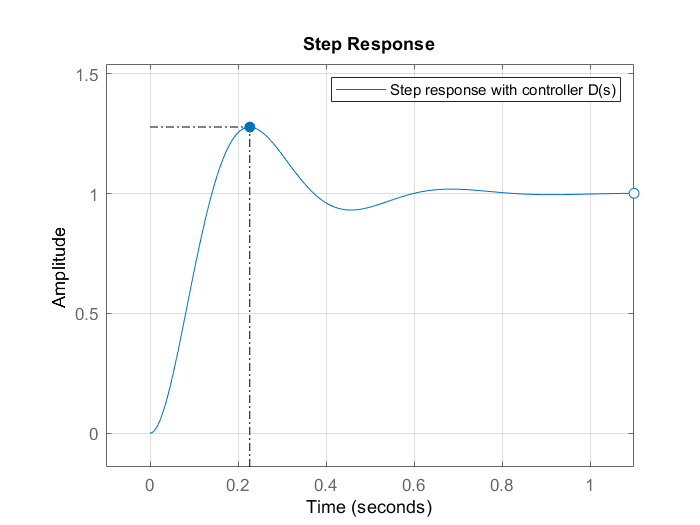

figure;
response = stepplot(Ls);
grid on;
response.showCharacteristic('PeakResponse');
response.showCharacteristic('SettlingTime');
response.showCharacteristic('RiseTime');
response.showCharacteristic('SteadyState');
setAxisLimits(axis);
legend('Step response with controller D(s)');

Time Domain parameters of system with controller.

stepinfo(Ls)

ans = struct with fields:
        RiseTime: 0.0952
    SettlingTime: 0.5612
     SettlingMin: 0.9312
     SettlingMax: 1.2771
       Overshoot: 27.7119
      Undershoot: 0
            Peak: 1.2771
        PeakTime: 0.2267


[gainMargin, phaseMargin, wcg, wcp] = margin(Ls)

gainMargin = Inf

phaseMargin = 66.5761

wcg = Inf

wcp = 17.8151

### Bode Plot of the closed loop transfer function.

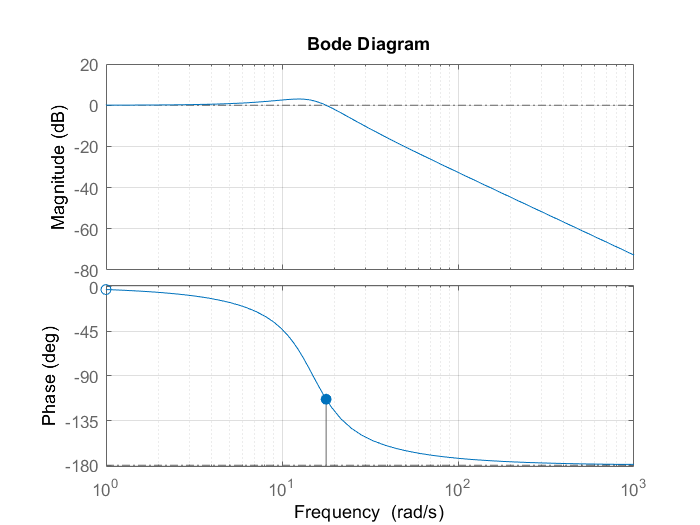

response = bodeplot(Ls);
response.showCharacteristic('AllStabilityMargins');
grid on;

We can see from the **bode plot **that once the gain crossed the **0db **point, it never crosses it back again, hence no matter what the gain is, the system is going to remain stable. 

Where as the phase when the gain crosses the **0db** is the **phase margin** and it's angle is 66.57°

### Nyquist Plot of the closed loop transfer function

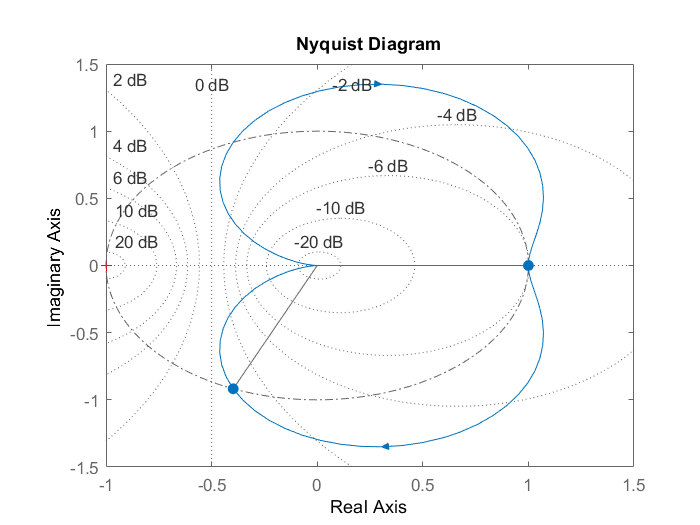

response = nyquistplot(Ls);
response.showCharacteristic('AllStabilityMargins');
grid on;

### Inference

Since the **Gain Margin is infinity**, any amount of gain will not result in system getting unstable, this can be shown in the Nyquist plot.

**Phase Margin is 66.5761**, this means that the system is stable for any value on phase but not 66.5761. As seen on the Nyquist plot, At a gain of **0db**, the plot touches the -1 point at an angle of 66.5761 degrees.